%% select data and map it to the RAM
nam = "\\Data-Server-2\个人数据\张天夫\202501\测试.tif";
[data,Ysiz,d1,d2,numFrame]=UniExp.CnmfeChooseData(nam);


The data has been mapped to RAM. It has 512 X 512 pixels X 2000 frames. 
Loading all data requires 3.91 GB RAM



%% create Source2D class object for storing results and parameters
Fs = 8;             % frame rate
ssub = 1;           % spatial downsampling factor
tsub = 1;           % temporal downsampling factor
gSig = 3;           % width of the gaussian kernel, which can approximates the average neuron shape
gSiz = 31;          % maximum diameter of neurons in the image plane. larger values are preferred.
neuron_full = UniExp.Sources2D('d1',d1,'d2',d2, ... % dimensions of datasets
    'ssub', ssub, 'tsub', tsub, ...  % downsampleing
    'gSig', gSig,...    % sigma of the 2D gaussian that approximates cell bodies
    'gSiz', gSiz);      % average neuron size (diameter)
neuron_full.Fs = Fs;         % frame rate

% with dendrites or not 
with_dendrites = false;
if with_dendrites
    % determine the search locations by dilating the current neuron shapes
    neuron_full.options.search_method = 'dilate'; 
    neuron_full.options.bSiz = 20;
else
    % determine the search locations by selecting a round area
    neuron_full.options.search_method = 'ellipse';
    neuron_full.options.dist = 3;
end

merge_thr = [1e-1, 0.85, 0];     % thresholds for merging neurons; [spatial overlap ratio, temporal correlation of calcium traces, spike correlation]
min = 1;

%% options for running deconvolution 
neuron_full.options.deconv_flag = true; 
neuron_full.options.deconv_options = struct('type', 'ar1', ... % model of the calcium traces. {'ar1', 'ar2'}
    'method', 'foopsi', ... % method for running deconvolution {'foopsi', 'constrained', 'thresholded'}
    'smin', -5, ...         % minimum spike size. When the value is negative, the actual threshold is abs(smin)*noise level
    'optimize_pars', true, ...  % optimize AR coefficients
    'optimize_b', true, ...% optimize the baseline);
    'max_tau', 100);    % maximum decay time (unit: frame);


%% downsample data for fast and better initialization
sframe=1;						% user input: first frame to read (optional, default:1)
num2read= numFrame;             % user input: how many frames to read   (optional, default: until the end)

tic;
[neuron,Y,T] = UniExp.CnmfeLoadData(ssub,tsub,neuron_full,data,sframe,num2read);


The data has been loaded into RAM. It has 512 X 512 pixels X 2000 frames. 
Loading all data requires 3.91 GB RAM



fprintf('Time cost in downsapling data:     %.2f seconds\n', toc);

Time cost in downsapling data:     9.46 seconds



Y = neuron.reshape(Y, 1);       % convert a 3D video into a 2D matrix

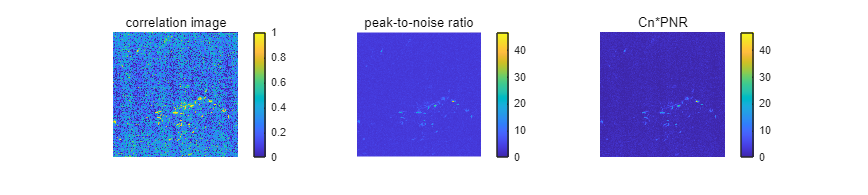


%% compute correlation image and peak-to-noise ratio image.
UniExp.CnmfeShowCorrPnr(neuron,Y,T);    % this step is not necessary, but it can give you some...

                        % hints on parameter selection, e.g., min_corr & min_pnr


%% initialization of A, C
% parameters
debug_on = true;   % visualize the initialization procedue. 
save_avi = false;   %save the initialization procedure as an avi movie. 
patch_par = [1,1]*1; %1;  % divide the optical field into m X n patches and do initialization patch by patch. It can be used when the data is too large 
K = []; % maximum number of neurons to search within each patch. you can use [] to search the number automatically

min_corr = 0.8;     % minimum local correlation for a seeding pixel
min_pnr = 8;       % minimum peak-to-noise ratio for a seeding pixel
min_pixel = gSig^2;      % minimum number of nonzero pixels for each neuron
bd = 1;             % number of rows/columns to be ignored in the boundary (mainly for motion corrected data)
neuron.updateParams('min_corr', min_corr, 'min_pnr', min_pnr, ...
    'min_pixel', min_pixel, 'bd', bd);
neuron.options.nk = 5;  % number of knots for detrending 

% greedy method for initialization
tic;
[center, Cn, pnr] = neuron.initComponents_endoscope(Y, K, patch_par, debug_on, save_avi);
fprintf('Time cost in initializing neurons:     %.2f seconds\n', toc);

% show results
figure;
imagesc(Cn, [0.1, 0.95]);
hold on; plot(center(:, 2), center(:, 1), 'or');
colormap; axis off tight equal;

% sort neurons
neuron.orderROIs('snr');
neuron_init = neuron.copy();


%% iteratively update A, C and B
% parameters, merge neurons
display_merge = false;          % visually check the merged neurons
view_neurons = false;           % view all neurons

% parameters, estimate the background
spatial_ds_factor = 1;      % spatial downsampling factor. it's for faster estimation
thresh = 10;     % threshold for detecting frames with large cellular activity. (mean of neighbors' activity  + thresh*sn)

bg_neuron_ratio = 1.5;  % spatial range / diameter of neurons

% parameters, estimate the spatial components
update_spatial_method = 'hals';  % the method for updating spatial components {'hals', 'hals_thresh', 'nnls', 'lars'}
Nspatial = 5;       % this variable has different meanings: 
                    %1) udpate_spatial_method=='hals' or 'hals_thresh',
                    %then Nspatial is the maximum iteration 
                    %2) update_spatial_method== 'nnls', it is the maximum
                    %number of neurons overlapping at one pixel 
               
% parameters for running iteratiosn 
nC = size(neuron.C, 1);    % number of neurons 

maxIter = 2;        % maximum number of iterations 
miter = 1; 
while miter <= maxIter
    %% merge neurons
    UniExp.CnmfeQuickMerge(neuron,merge_thr,display_merge,view_neurons);              % run neuron merges
    UniExp.CnmfeMergeNeighbors(neuron,dmin,display_merge,view_neurons);          % merge neurons if two neurons' peak pixels are too close 
    
    %% udpate background 
    % estimate the background
    tic;
    [Ybg_weights,Ysignal] = UniExp.CnmfeUpdateBg(Y,neuron,bg_neuron_ratio,spatial_ds_factor,thresh);
    fprintf('Time cost in estimating the background:        %.2f seconds\n', toc);
    % neuron.playMovie(Ysignal); % play the video data after subtracting the background components.
    
    %% update spatial & temporal components
    tic;
    for m=1:2  
        %temporal
        neuron.updateTemporal_endoscope(Ysignal);
        UniExp.CnmfeQuickMerge(neuron,merge_thr,display_merge,view_neurons);              % run neuron merges
        %spatial
        neuron.updateSpatial_endoscope(Ysignal, Nspatial, update_spatial_method);
        
        % post process the spatial components (you can run either of these two operations, or both of them)
        neuron.trimSpatial(0.01, 3); % for each neuron, apply imopen first and then remove pixels that are not connected with the center
        neuron.compactSpatial();    % run this line if neuron shapes are circular 
        UniExp.CnmfeMergeNeighbors(neuron,dmin,display_merge,view_neurons); 
        
        % stop the iteration when neuron numbers are unchanged. 
        if isempty(merged_ROI)
            break;
        end
    end
    fprintf('Time cost in updating spatial & temporal components:     %.2f seconds\n', toc);
    
    %% pick neurons from the residual (cell 4).
    if miter==1
        seed_method = 'auto'; 
        [center_new, Cn_res, pnr_res] = neuron.pickNeurons(Ysignal - neuron.A*neuron.C, patch_par, seed_method, debug_on); % method can be either 'auto' or 'manual'
    end
    
    %% stop the iteration 
    temp = size(neuron.C, 1); 
    if or(nC==temp, miter==maxIter)
        break; 
    else
        miter = miter+1; 
        nC = temp; 
    end
end

%% apply results to the full resolution
if or(ssub>1, tsub>1)
    neuron_ds = neuron.copy();  % save the result
    neuron = neuron_full.copy();
    cnmfe_full;
    neuron_full = neuron.copy();
end


%% delete some neurons and run CNMF-E iteration 
neuron.orderROIs('decay_time');  % you can also use {'snr', 'mean', 'decay_time'} 
neuron.viewNeurons([], neuron.C_raw); 
tic;
[Ybg_weights,Ysignal] = UniExp.CnmfeUpdateBg(Y,neuron,bg_neuron_ratio,spatial_ds_factor,thresh);
fprintf('Time cost in estimating the background:        %.2f seconds\n', toc);
%update spatial & temporal components
tic;
for m=1:2
    %temporal
    neuron.updateTemporal_endoscope(Ysignal);
    UniExp.CnmfeQuickMerge(neuron,merge_thr,display_merge,view_neurons);              % run neuron merges

    %spatial
    neuron.updateSpatial_endoscope(Ysignal, Nspatial, update_spatial_method);
    neuron.trimSpatial(0.01, 3); % for each neuron, apply imopen first and then remove pixels that are not connected with the center
    neuron.compactSpatial(); 
    UniExp.CnmfeMergeNeighbors(neuron,dmin,display_merge,view_neurons); 
end
fprintf('Time cost in updating spatial & temporal components:     %.2f seconds\n', toc);

b0 = mean(Y,2)-neuron.A*mean(neuron.C,2); 
Ybg = bsxfun(@plus, Ybg, b0-mean(Ybg, 2)); 
neuron.orderROIs('snr'); 

%% display neurons
dir_neurons = sprintf('%s%s%s_neurons%s', dir_nm, filesep, file_nm, filesep);
neuron.save_neurons(dir_neurons); 

%% display contours of the neurons
figure;
Cnn = UniExp.CorrelationImage(neuron.reshape(Ysignal(:, 1:5:end), 2), 4);
neuron.show_contours(0.6); 
colormap gray;
axis equal; axis off;
title('contours of estimated neurons');

% plot contours with IDs
% [Cn, pnr] = neuron.correlation_pnr(Y(:, round(linspace(1, T, min(T, 1000)))));
figure;
Cn = imresize(Cn, [d1, d2]); 
neuron.show_contours(0.6); 
colormap gray;
title('contours of estimated neurons');

%% check spatial and temporal components by playing movies
save_avi = false;
avi_name = 'play_movie.avi';
neuron.Cn = Cn;
neuron.runMovie(Ysignal, [0, 150], save_avi, avi_name);

%% save video
kt = 3;     % play one frame in every kt frames
save_avi = true;
center_ac = median(max(neuron.A,[],1)'.*max(neuron.C,[],2)); % the denoised video are mapped to [0, 2*center_ac] of the colormap 
UniExp.CnmfeSaveVideo(neuron,Y,Ybg,Ysignal,save_avi,kt=kt,avi_filename=avi_name);

%% save results
results = neuron.obj2struct(); 
eval(sprintf('save %s%s%s_results.mat results', dir_nm, filesep, file_nm));